# Visión por Computador - Sessió 9

    Ferran Velasco Olivera

    Joaquín Gómez Sánchez

## Processat + Segmentació + Etiquetat + Descripció de regions

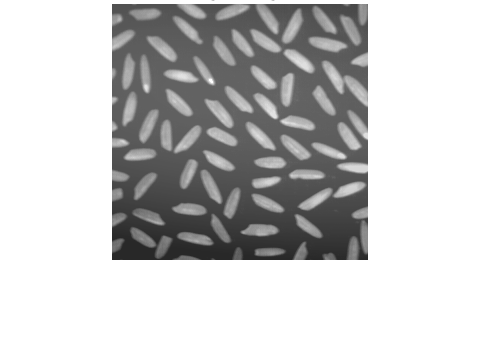

orig = imread('arros.tif');
imshow(orig), title('imatge original')

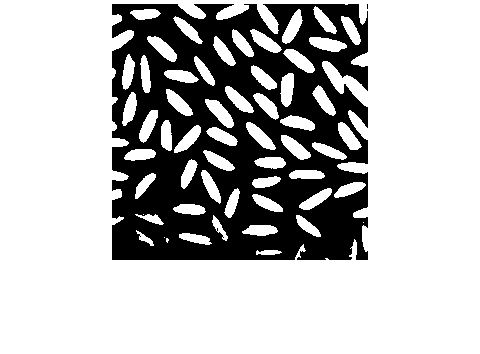

% segmentem per binarització
bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw),title('Threshold automatic')

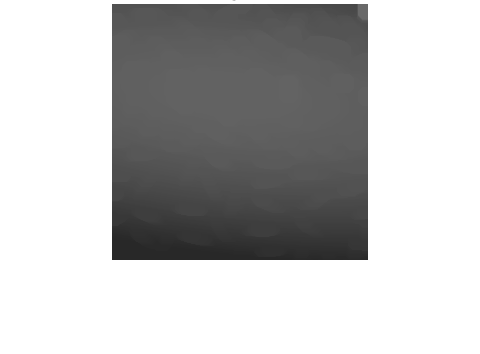

% No funciona, perdem grans. No confieu mai en els detectors automatics de llindar.
% El problema està en que la iluminació no és gens homogènea

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg),title('background')

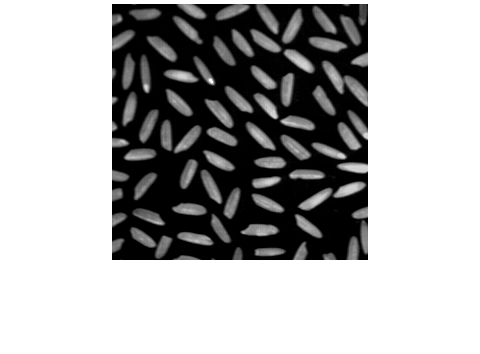

figure, surf(bg) % mostrem el background com si fos una superfície
%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title( 'top hat')

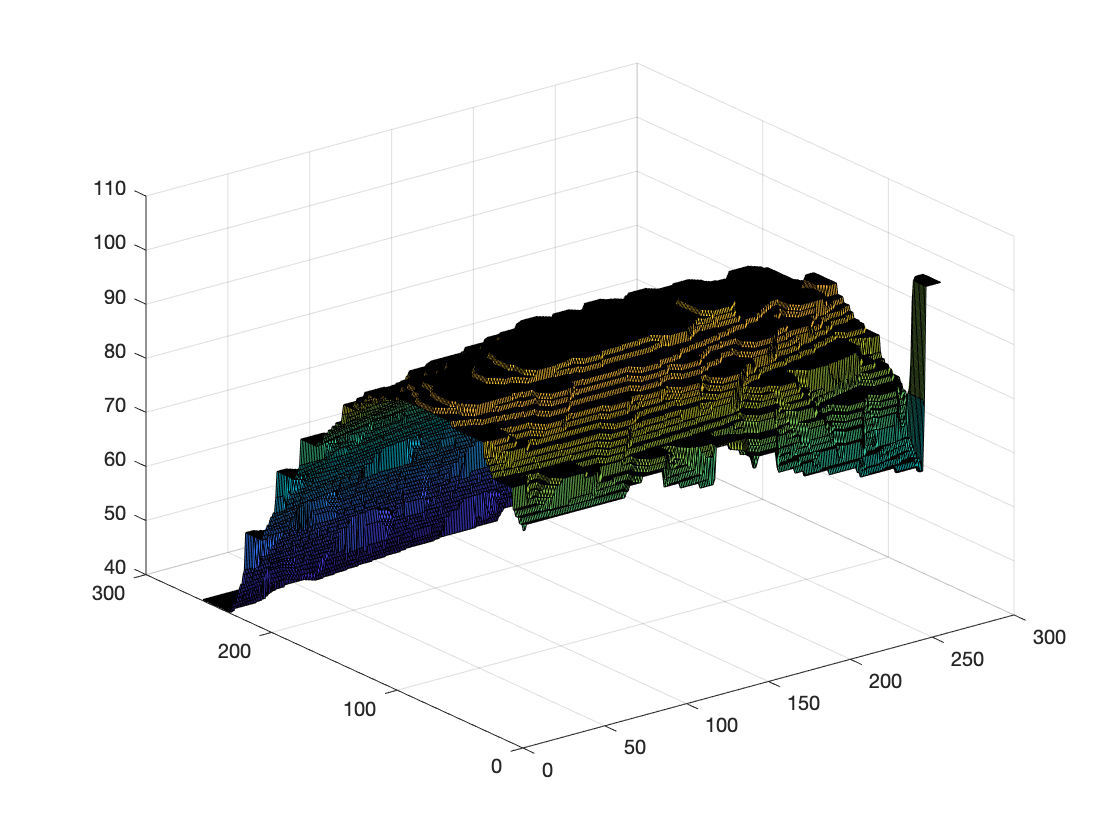

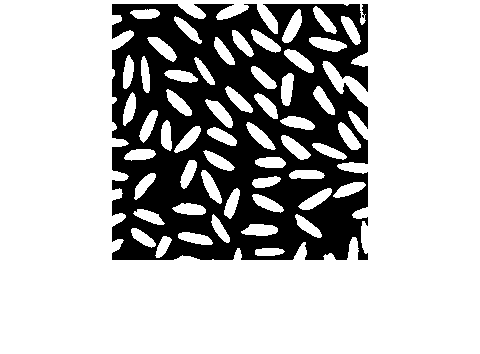

% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic')

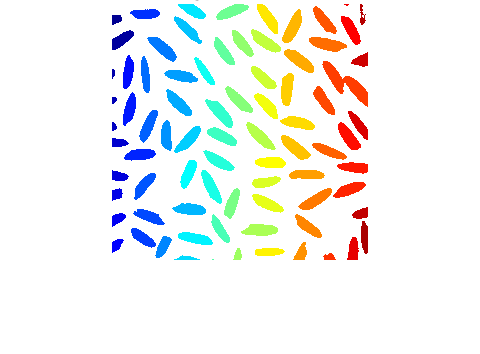

%Ara si!

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')


% Comptem ara el nombre d’objectes a la imatge
num

num = 81

%o be:
max(eti(:))

ans = 81


% obtenim descriptors de les regions
Dades = regionprops(eti,'all')

Dades = 81×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


% Comproveu en el workspace la variable Dades. Quines propietats hem extret de cada regió?
% Consulteu el help de la funció regionprops.
 % Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area

ans = 305

% O be un vector amb totes les Àrees:
Arees=[Dades.Area];

#### Exercici

En la imatge segmentada, separeu els grans d%arròs que es toquen. Desprès elimineu els grans d'arròs que toquen les vores. Tots aquests grans falsejaven el resultat. Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops.

Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants per a fer un control de qualitat dels grans d'arròs.

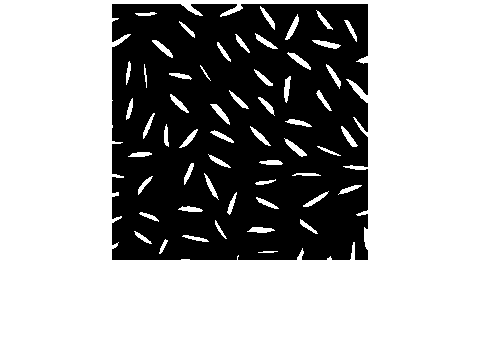

% Separar grans d'arros
ee = strel('disk',4);
seg = imerode(bw, ee);
imshow(seg)

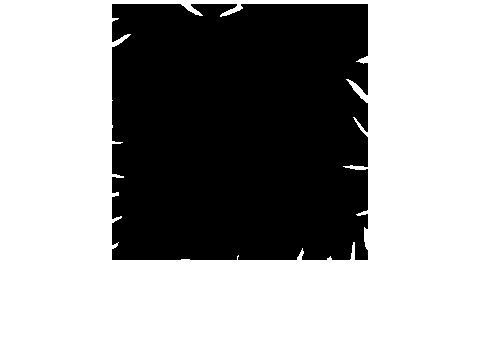


% eliminar grans d'arros de les vores
mark = true(size(seg)); 
mark(2:end-1, 2:end-1) = 0;
touchingBorders = imreconstruct(mark, seg); 
imshow(touchingBorders)

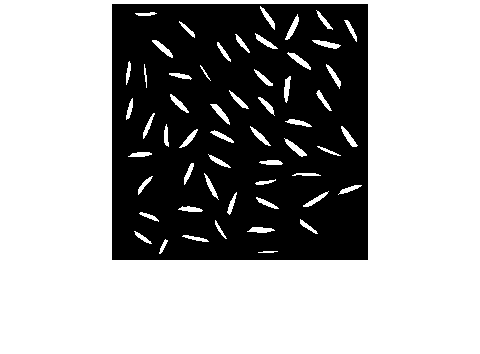

noBorders = seg - touchingBorders;
imshow(noBorders)

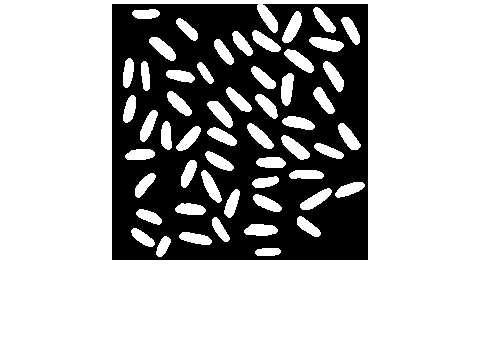

final = imreconstruct(logical(noBorders), seg);
final = imdilate(final, ee);
imshow(final)

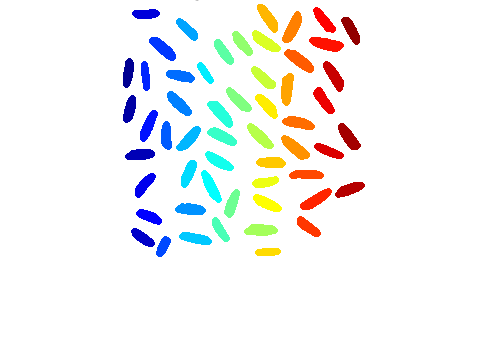


% labeling
[eti num] = bwlabel(final,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')


% obtenim descriptors de les regions
Dades = regionprops(eti,'all')

Dades = 55×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


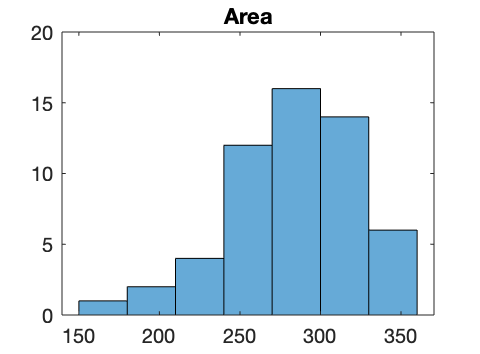


% Observem les distribucions de diferents atributs
Arees=[Dades.Area];
histogram(Arees), title('Area')

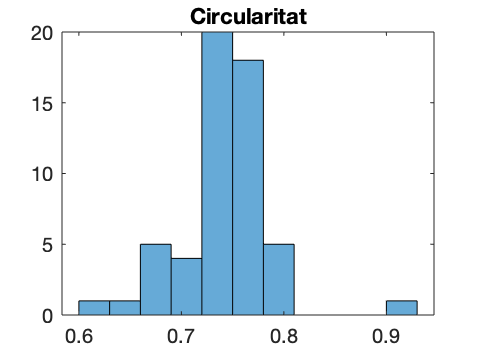


Circularities = [Dades.Circularity];
histogram(Circularities), title('Circularitat')

## Codis de cadena

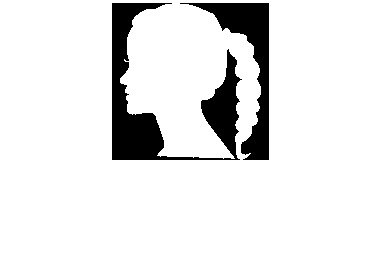

clear all, close all
im=imread('head.png');
% no cal tan gran
im=imresize(im,1/4);
imshow(im), title('imatge original')

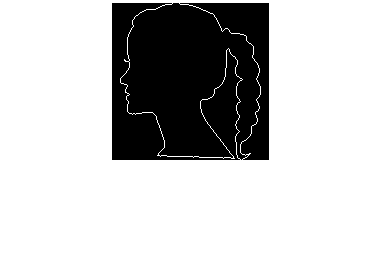


% obtenim el contorn
ero=imerode(im,strel('disk',1));
cont=xor(ero,im);
figure,imshow(cont), title('contorns')

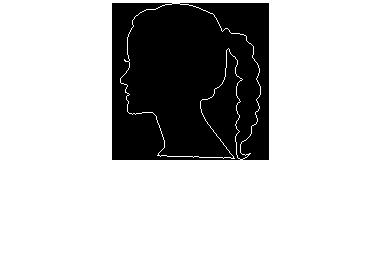


% obtenim les coordenades del contorn
[fila col] = find(im,1); % Busquem el primer píxel
B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades

% Ho comprovem mostrant el resultat
aux=zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure,imshow(aux),title ('contorns a partir de coordenades')

#### Exercici

    Trobar els codis de cadena incrementals a partir de B

incrementalChain = codiCadenaIncremental(B);

incrementalChain =      0
     0
     0
     0
     0
     1
     7
     0
     1
     7


## Descriptors de Fourier

% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);

% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);

% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end

% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))
% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')

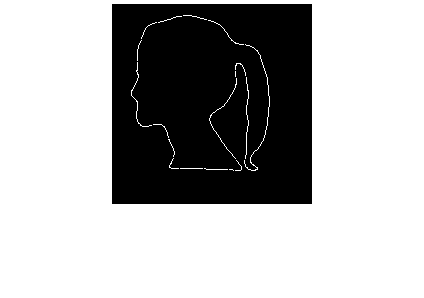


%% Reduim la quantitat de descriptors de Fourier
N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

#### Exercici

Repetiu el procés utilitzant diferents quantitats de descriptors i expliqueu quin efecte té això en el detall de la imatge obtinguda

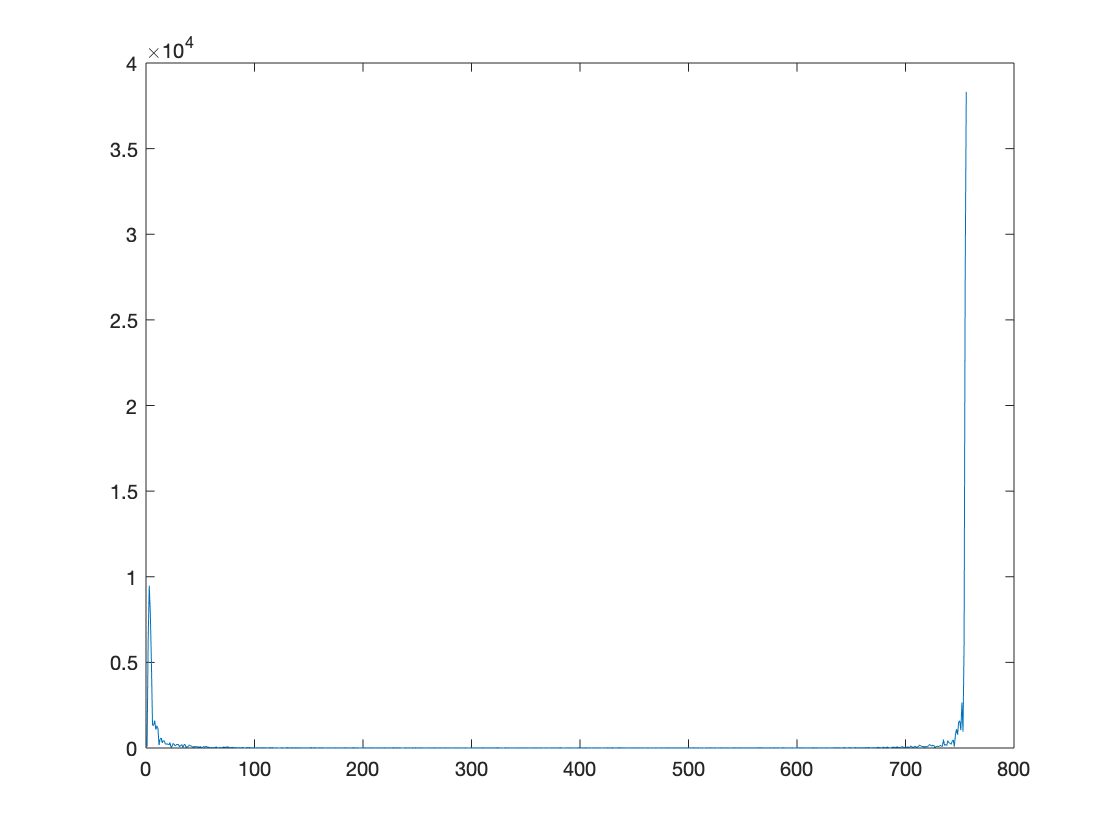

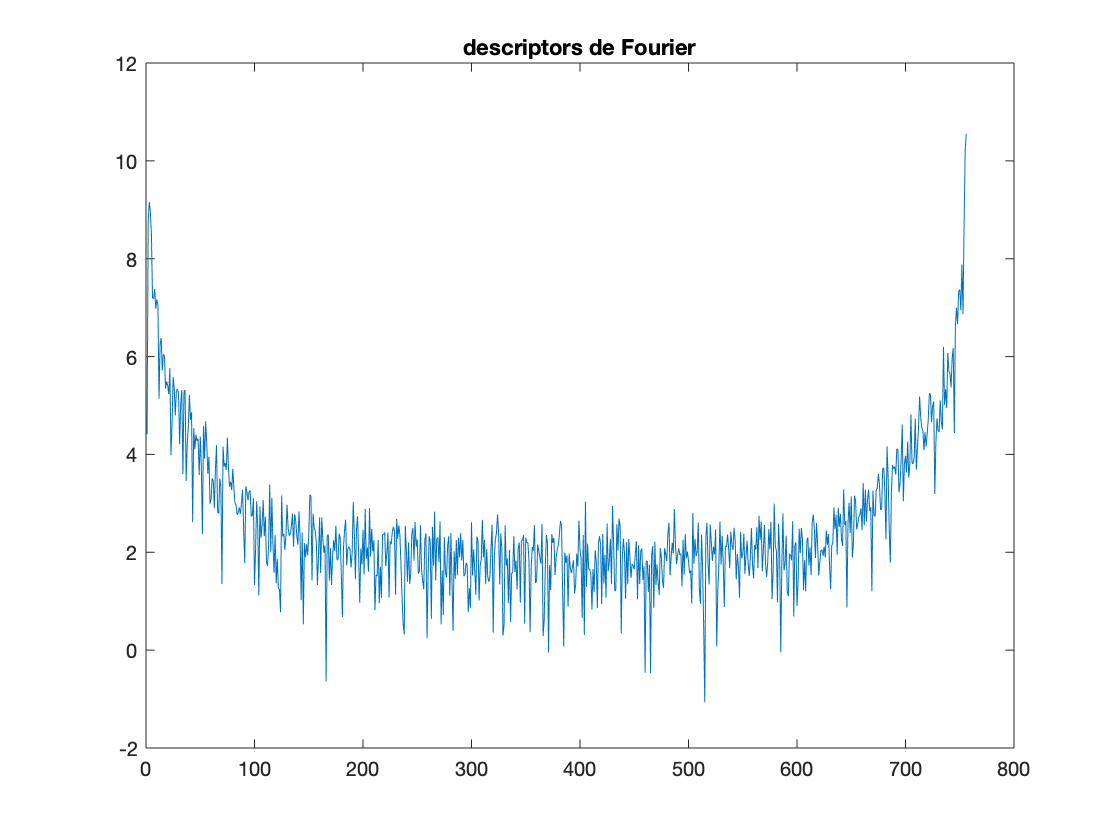

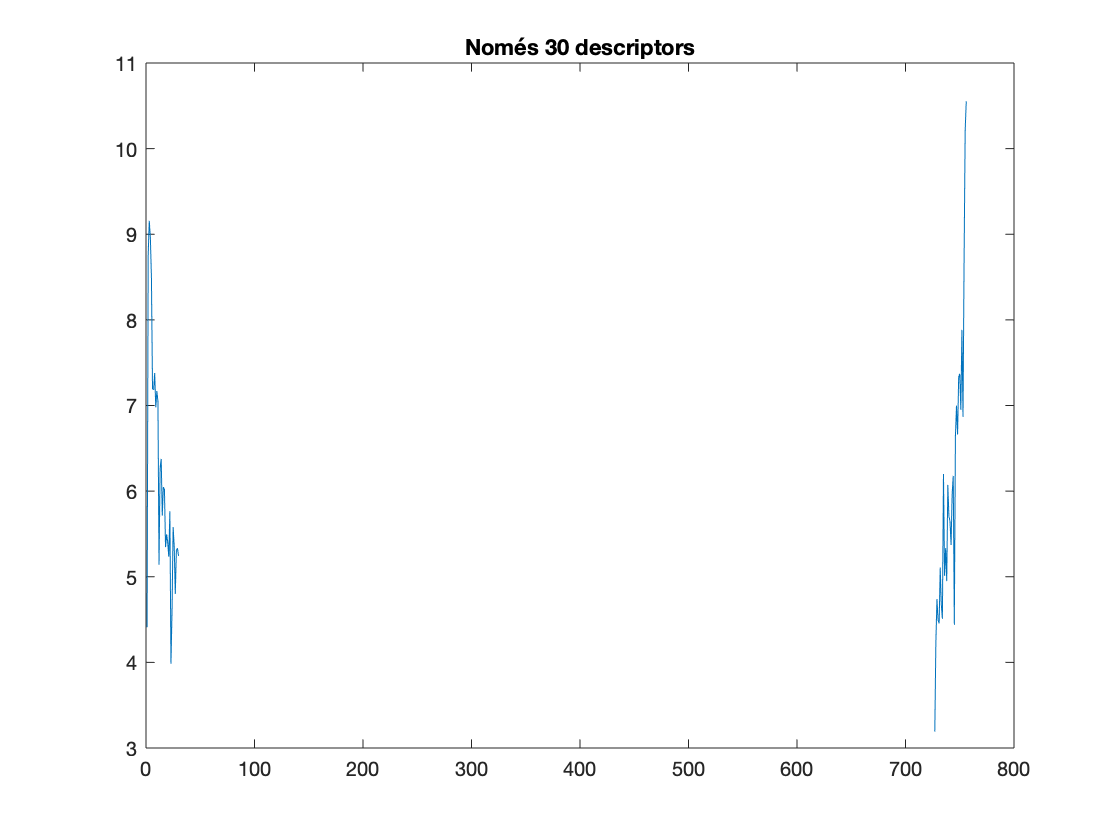

N=10; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 10 descriptors')

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)

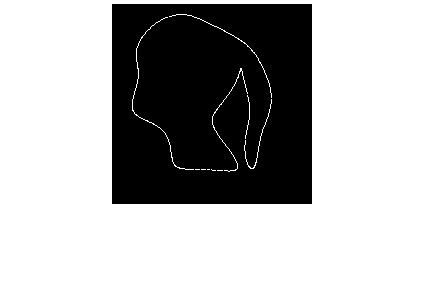

title(['Numero de descriptors: ',num2str(N)]);

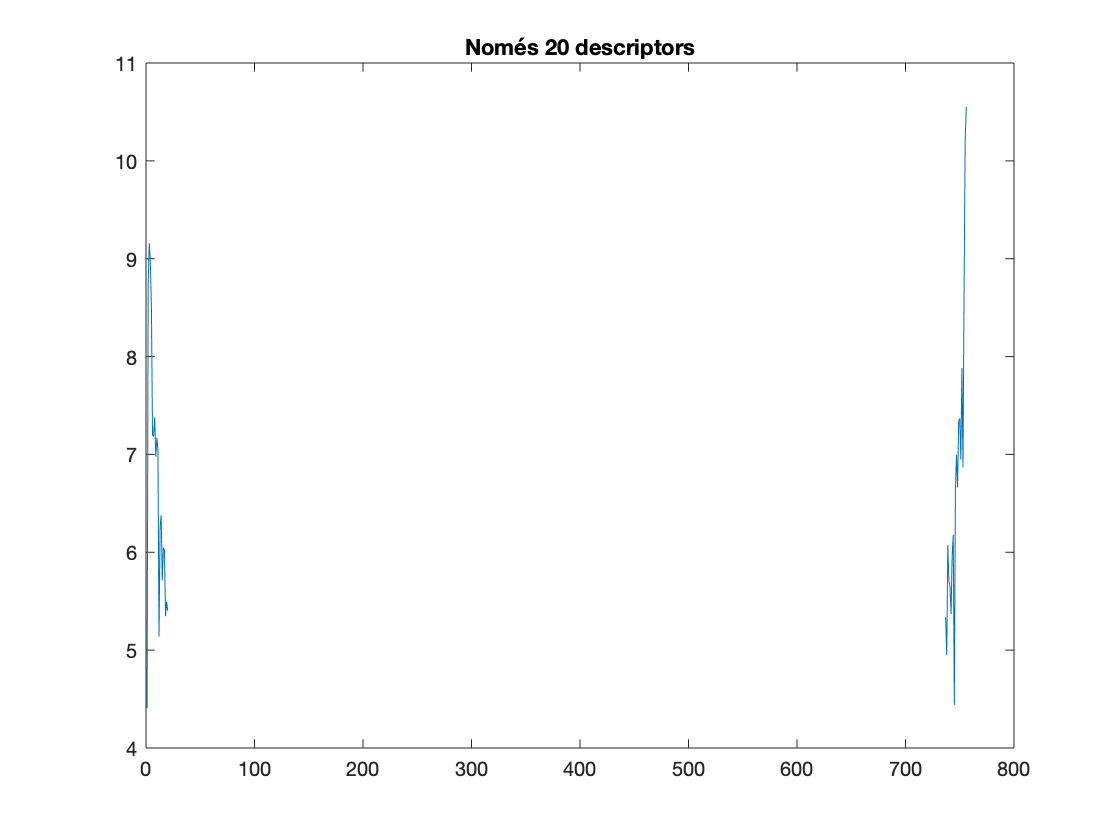


N=20; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 20 descriptors')

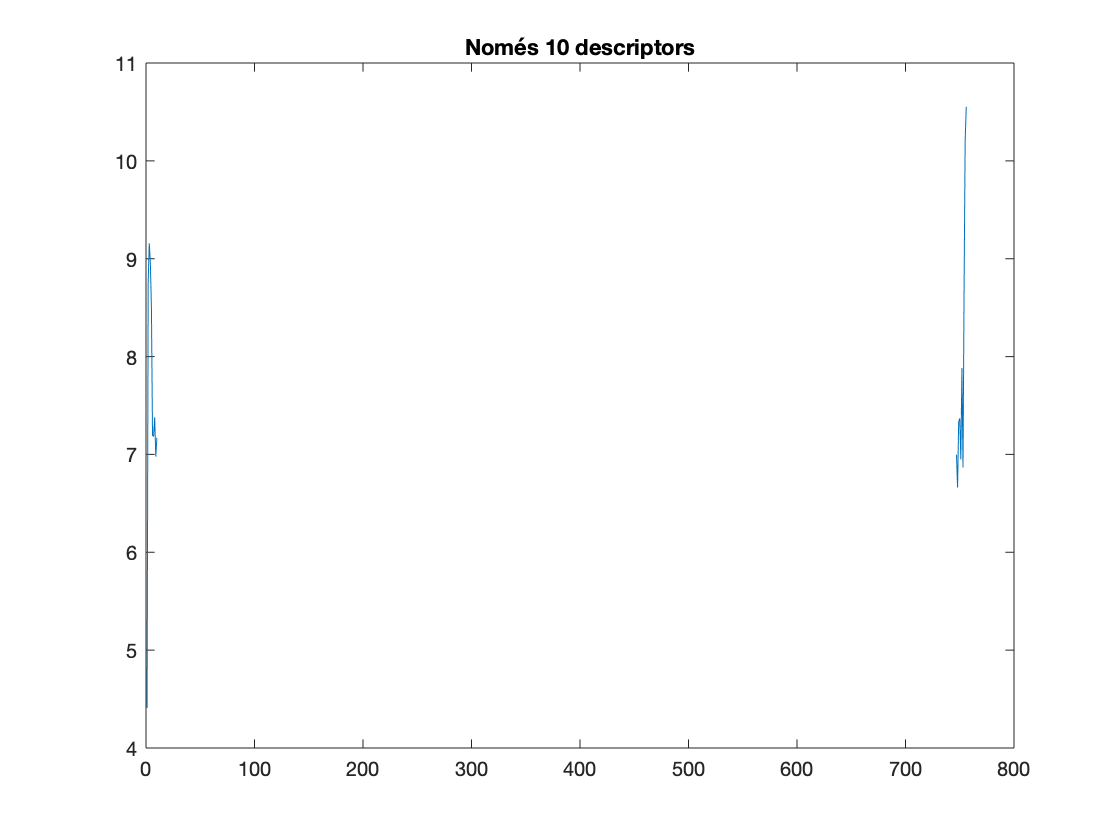


% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)

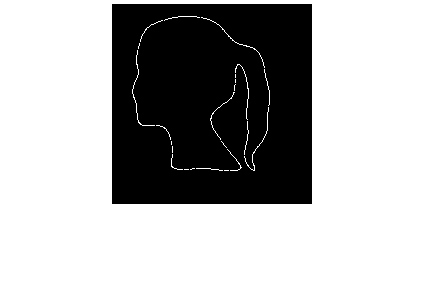

title(['Numero de descriptors: ',num2str(N)]);

Explicació: Quant més gran és el número de descriptors de fourier emprats, el nivell de fidelitat del contorn és més elevat. Per tant, en quant més descriptors s'utilitzin, més semblant serà el contorn a la imatge original. 

## Funcions

function incrementalChain = codiCadenaIncremental(B)
    [n m] = size(B);
    chain = zeros(n-1, 1);
    
    % calcul del codi de cadena
    for i=1:(n-1)
        D = B(i+1, :)-B(i, :);
        if (D(1) == -1 && D(2) == 0)
            chain(i) = 1;
        elseif(D(1) == -1 && D(2) == -1)
            chain(i) = 2;
        elseif(D(1) == 0 && D(2) == -1)
            chain(i) = 3;
        elseif(D(1) == 1 && D(2) == -1)
            chain(i) = 4;
        elseif(D(1) == 1 && D(2) == 0)
            chain(i) = 5;
        elseif(D(1) == 1 && D(2) == 1)
            chain(i) = 6;
        elseif(D(1) == 0 && D(2) == 1)
            chain(i) = 7;
        elseif(D(1) == -1 && D(2) == 1)
            chain(i) = 8;
        end
            
    end
    
    % cadena incremental
    incrementalChain = mod(diff(chain), 8)
end